# Laboratorium 3

# Analiza harmoniczna - część 1

Karolina Piotrowska

Zadanie 1

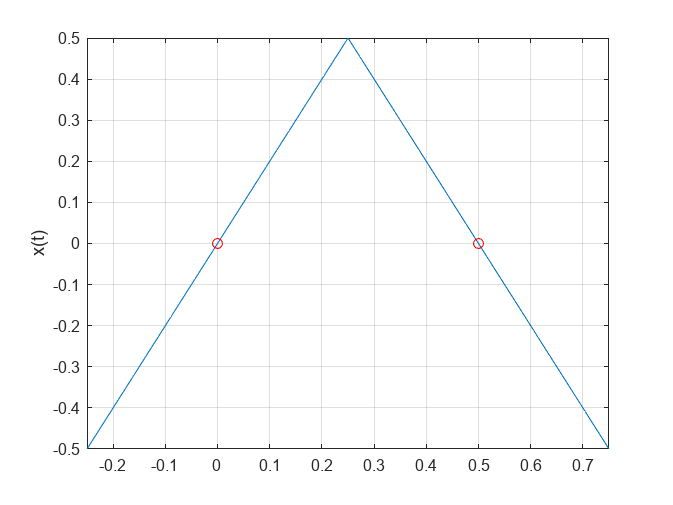

syms t t1 t2 offset x

T0 = 1.0;
t1 = -0.5;
t2 = t1 + T0;

offset = T0/4;

f0 = 1/T0;

w0 = 2*pi*f0;

BND = [t1,t2] + offset;

x = triangularPulse(t1, 0.0, t2, t-offset) - 0.5;

figure
fplot(x, BND), grid on, ylabel('x(t)')
hold on
plot(0, 0, 'ro') %punkty zmiany znaku sygnału
plot(0.5, 0, 'ro')
hold off

Zadanie 2

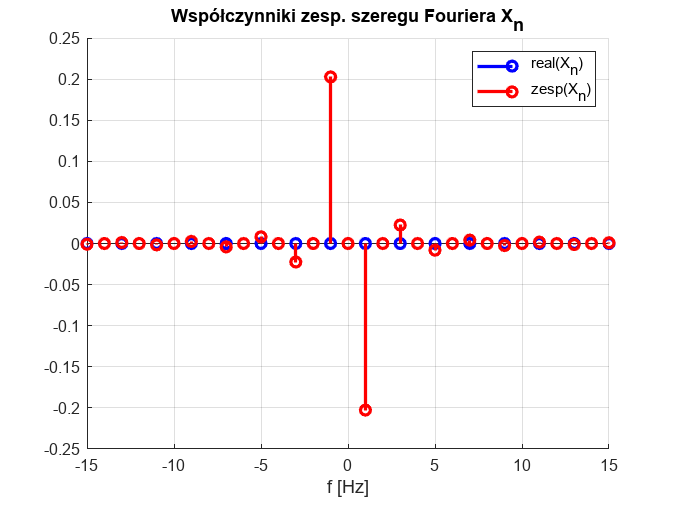

NT = 15;

X=[];

ind = -NT:NT;

for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end

figure
hold on
stem(ind*f0, real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0, imag(X),'r','LineWidth',2);
grid on
legend('real(X_n)','zesp(X_n)','Location','NorthEast'),
title('Współczynniki zesp. szeregu Fouriera X_n')

Zadanie 3

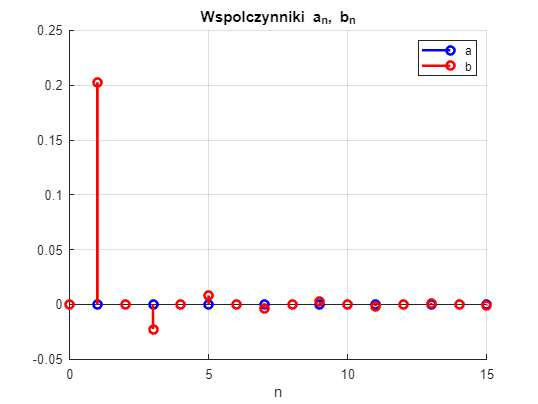

NT = 0:15;
a=[];
b=[];

for n = NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure; 
grid on
hold on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
legend('a','b'),
title('Wspolczynniki a_n, b_n')
hold off

Zadanie 4

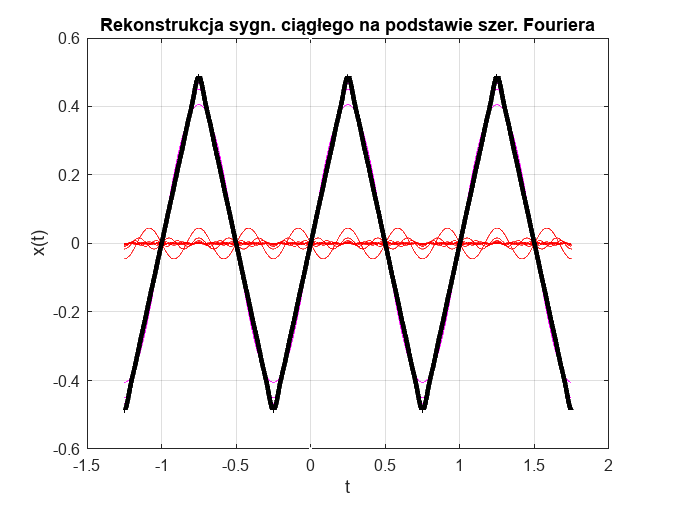

NT = 15

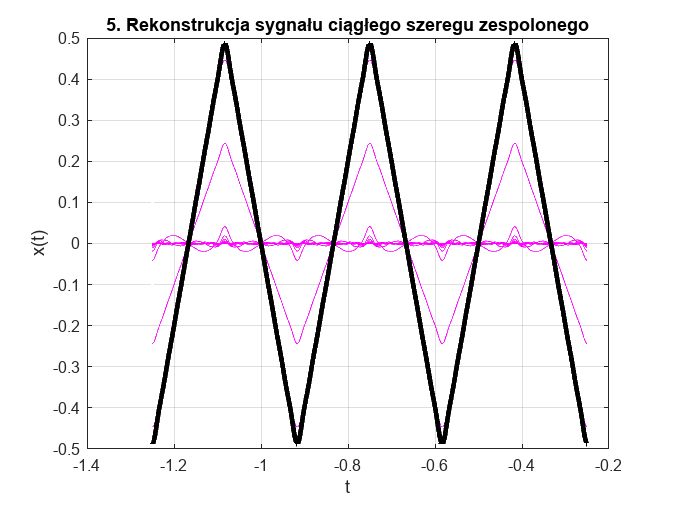

s = 0

s = 2.5348e-04

s = 2.5348e-04

s = 2.8633e-04

s = 2.8633e-04

s = 2.9488e-04

s = 2.9488e-04

s = 2.9801e-04

s = 2.9801e-04

s = 2.9942e-04

s = 2.9942e-04

s = 3.0013e-04

s = 3.0013e-04

s = 3.0054e-04

thd = 0.1210

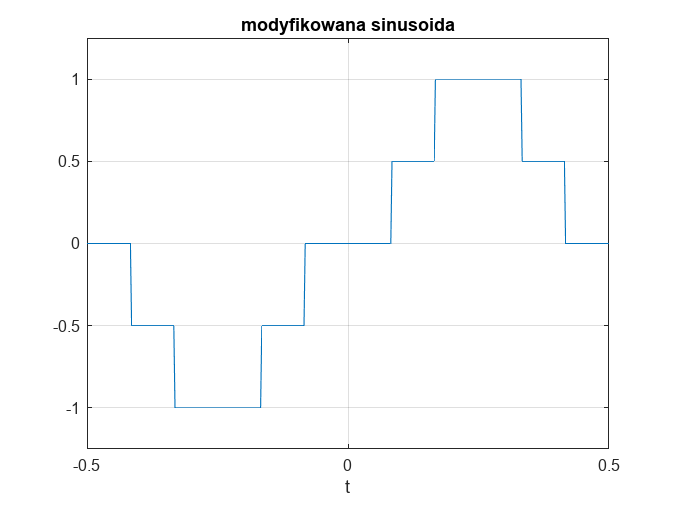

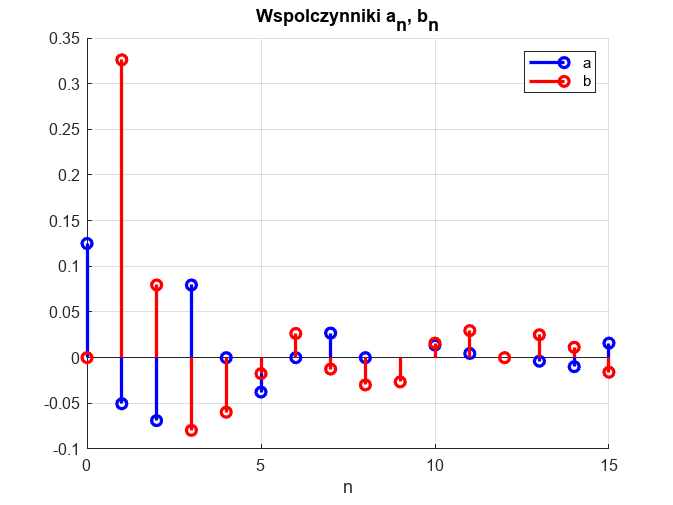

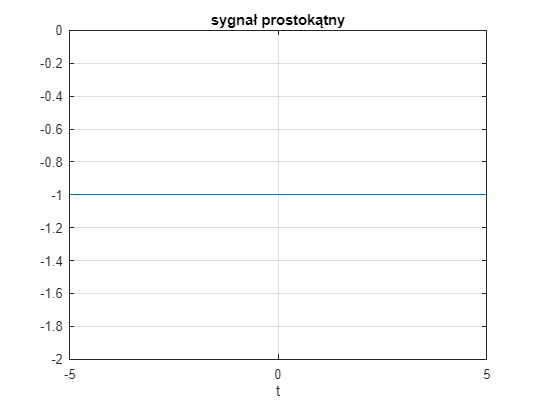

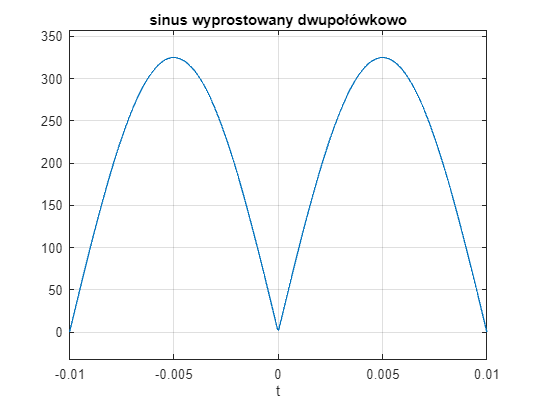

step = (BND(2)-BND(1))/1000;

tt = [BND(1)-T0 : step : BND(2) + T0];

xx = zeros(1,length(tt));
xx = xx + a(1);

figure;
plot(tt,xx,'m')
grid on 
hold on
plot([0, 0],[-0.6, 0.6], 'w.'),
xlabel('t'); ylabel('x(t)');
pause(0.5)

for n = NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    title(sprintf('n = %d',n+1));
    pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygn. ciągłego na podstawie szer. Fouriera')
hold off